# NetGEN 

## Automatic Generation of Chemical Reactor Networks from CFD data

## Guided Example

### Configure the main options for the code

The main function to create CRN using Machine Learing with graph algorithms is the following functions:

% [mass_corrected, bc_mass_flowrates, R_list, idx, X, infos] = ...
%     network_eval(k, inlet_streams, case_info, opt_global)

As you can see, the functions requires:

- `k` = number of clusters (integer)

- inlet_streams = dictionary with information about the inlets (see example below)

- case_info = dictionary with information regarding boundary conditions (see example below)

- opt_global = dictionary with global options for the code (see example below and network_eval.m)

In this live example, the main options for the NetGEN suite will be described. In this version of the code, the CFD code FLUENT was used, and User Defined Functions to export the necessary data are provided. This version of the code has also a built-in interface with the reactor network solver **NetSMOKE++,** which can be provided for non commercial use by asking for a license to **alberto.cuoci@polimi.it. **

In this example, the main options to customize your automatic CRN generation will be described.

#### Mandatory input files

In this basic tutorial, we are going to define the main options for the automatic clustering of CFD data. First of all, we need to import the basic files that we need by providing their path and filenames to a opt_global struct variable, in the following way:

%%% File names and path to CFD files %%%
opt_global.DataPath = '/Users/matteosavarese/Desktop/Dottorato/Github/NetGEN/Example/';

% Ascii files
opt_global.SolutionFile = 'data_solution';
opt_global.VolumeFile = 'data_volumes';
opt_global.DensityFile = 'data_density';
opt_global.VelocityFile = 'data_velocity';

% Connectivity file (see export_faces_neighbors.c)
opt_global.ConnectivityFile = 'Neighbours_cell_flows';
opt_global.BoundaryCellsFile = 'Boundary_cells';


The `data_solution `is the .txt (or .csv, or ascii) file exported from the CFD simulation, which contain, for each row, the temperature as the first variable and mass (or mol) fractions as the other columns. The files `data_volumes, data_density, data_velocity `have the same format, although containing volumes [cm3], density [kg/m3] and velocity magnitude [m/s] in the cell **centroids. **

The file `Neighbours_cell_flows `contains information about the connectivity of the cells, their mass flowrate exchanged [kg/s] and the area of the face that separates them [m2]. It is necessary to estimate convective (and diffusive) mass flowrates across clusters

#### Customized input files

Other than necessary files, this code can include also the **velocity angle **and **residence time,  **as variables:

%%% Custom files %%%
opt_global.AngleFile = 'data_angle';
opt_global.TauFile   = 'data_tau';

Other input files can also be provided, and they will also affect the final solution of the resulting Chemical Reactor Network. In this code, temperature fluctuations effect on the average kinetic rates can be taken into account by providing the option for the **temperature RMS** file, as follows:

%%% Temperature fluctuations effects options %%%
opt_global.KineticCorrections = true;           % For simulations
opt_global.DataVariance = true;                 % For simulations
opt_global.TVarianceFile = 'data_variance';     % For data processing

If also **diffusive fluxes **need to be included in the simulation, data of effective viscosity [kg/m/s] must be provided:

%%% Diffusive fluxes options %%%
opt_global.Diffusion = true;                    % For simulations
opt_global.ViscosityFile = 'data_viscosity';    % For data processing

### Data pre processing

In this section, we will preprocess the imported data by specifying options regarding:

- Set of variables to use

- Centering criterion

- Scaling criterion

Indeed, centering and scaling are fundamental operations before starting any Machine Learning pipeline. 

Consider an observation $x_{ij}$, meaning that we are referring to the i-th point and the j-th feature, it can be centered, and scaled, as follows:


$$\tilde{x_{ij}} = \frac{x_{ij} - c_j}{d_j}$$


where $c_{j\;}$is usually the mean of the j-th feature and $d_j \;$is a scaling factor (usually standard deviation of the j-th variable)

Available centering and scaling criteria are available, see the functions [../Matlab_Functions/DataPreProcessing/center.m](matlab:open('../Matlab_Functions/DataPreProcessing/center.m')) and [../Matlab_Functions/DataPreProcessing/scale.m](matlab:open('../Matlab_Functions/DataPreProcessing/scale.m')).

We provide options to the code as follows:

opt_global.OptData = 'reduced_set'  % See import_data_cfd.m for available options

opt_global = struct with fields:
              DataPath: '/Users/matteosavarese/Desktop/Dottorato/Github/NetGEN/Example/'
          SolutionFile: 'data_solution'
            VolumeFile: 'data_volumes'
           DensityFile: 'data_density'
          VelocityFile: 'data_velocity'
      ConnectivityFile: 'Neighbours_cell_flows'
             AngleFile: 'data_angle'
               TauFile: 'data_tau'
    KineticCorrections: 1
          DataVariance: 1
         TVarianceFile: 'data_variance'
             Diffusion: 1
         ViscosityFile: 'data_viscosity'
               OptData: 'reduced_set'
                Center: 1
                 Scale: 'auto'
                   Alg: 'k-means'
                 Start: 'uniform'
               MaxIter: 1000
             Criterion: 'Euclidean'
     ReassignCriterion: 'volume'
       VolumeThreshold: 0.0100
           KineticMech: 'gri2.11'
           SolveEnergy: 0
         RunSimulation: 0
     BoundaryCellsFile: 'Boundary_cells'
                 Basis

opt_global.Center = true;           % With true it will be centered 
opt_global.Scale  = 'auto';         % auto, pareto, vast...

In this case, we only use a reduced set of the state-space and flow variables, consisting of a progress variable, temperature, residence time, velocity magnitude and angle. Now we are ready to specify options for clustering

### **Clustering options**

Now, we must provide options for the unsupervised clustering routine. In particular, we must first select the algorithm. In this example, the **k-means **algorithm has been selected, and options must specified accordingly:

%%% Setup of k-means main options %%%
opt_global.Alg = 'k-means';         % also vqpca is available

% Customized options for k-means
opt_global.Start = 'uniform';       % For reproducibility (see the matlab function for k-means)
opt_global.MaxIter = 1000;          % Maximum number of iterations

If **VQPCA **routine is selected, several options are available, you can see them in the following commented lines:

% opt_global.Alg = 'vqpca';
% opt_global.Precond = false;         % Preconditioning based on mixture fraction (false by default)
% opt_global.StopRule = 'var';        % Stop pca.m rule based on variance retained (see custom_cluster.m)
% opt_global.Init     = 'uniform';    % Centroids initialization
% opt_global.Inputs   = 0.99          % Depends on stopping rule (see
%                                       vqpca.m)

Now that the unsupervised learning algorithms has been configured, we need to specify options for **graph reassignment**, if needed (**needed for CRN applications)**

### Graph Reassignment options

The peculiarity of this code, is that it can scan the unsupervised clusters and identify "disconnected components", as follows:

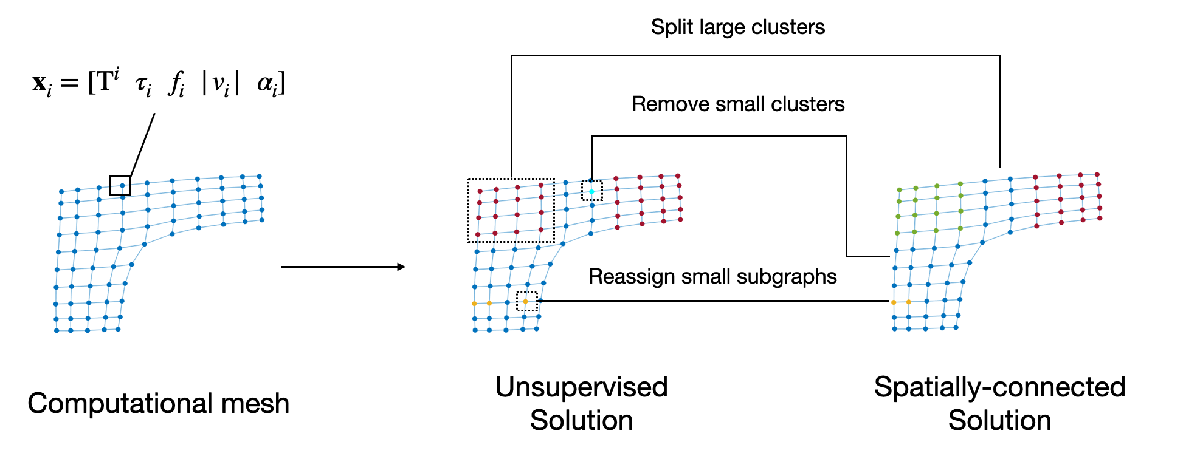

In this version of the code, the "big" clusters are splitted, creating new clusters, while the "small" clusters are reassigned to their "closest" neighbour. "Big" and "small" refers to their volume, therefore we must fix a relative volume threshold. "Closest", instead, refers to their distance, which can be geometric (only coordinates) or Euclidean (in a k-means framework, distance between their Euclidean multidimensional centroids).

Therefore, we must specify the following options: 

% Re-assign options
opt_global.Criterion = 'Euclidean';

% If Euclidean distance is selected, you can specify a matrix for the graph
% reassignment different from the one used for clustering
opt_global.ReassignCriterion = 'volume';
opt_global.VolumeThreshold = 0.01;

A basic example on how this graph reassignment works, you can see the [../Matlab_Functions/graph_test.m](matlab:open('../Matlab_Functions/graph_test.m')) script file.

Now, with the current interface with **NetSMOKE++, **we can specify the options to build the input files for the solver.

% Simulation options

% Kinetic mechanism
opt_global.KineticMech = 'gri2.11'; % gri3.0, gri2.11, SanDiego, Polimi, Stagni, Otomo

% Solve for energy equations in the reactors (false = isothermal case)
opt_global.SolveEnergy = false;

% Decide if simulation should be run on the fly
opt_global.RunSimulation = false;

% Decide if kinetic corrections and diffusion effects should be solved
opt_global.KineticCorrections = true;
opt_global.DataVariance = true;
opt_global.Diffusion = true;

Selecting `opt_global.SolveSimulation = false`, the simulation will not be run, this is if you do not have the CRN solver. However, you can still view the clustering results and the input files for the reactors will also be generated. In this way, you can gather all the required information to run a CRN simulation on your solver of choice

### **Running the simulation**

Finally, the main code can be run, as follows:

load case_info

% Select number of clusters
k = 10;

[mass_corrected, bc_mass_flowrates, R_list, idx, X, infos] = ...
     network_eval(k, inlet_streams, case_info, opt_global);

Case is 2-Dimensional
Data matrix X is of size 28175 rows and 5 columns 


Unrecognized function or variable 'clust_time_start'.

Error in network_eval (line 208)
infos.ClusteringTime = clust_time_end - clust_time_start;

The outputs of the code are:

- `mass_corrected `= matrix of mass flowrates across reactors

- `bc_mass_flowrates ` = matrix of inflows (first column) and outflows (second column) in the reactors

- `R_list = `dictionary with all the reactors information

- `idx = `clustering labelling vector

- `X` = matrix used for clustering

- `infos = `all information that can be useful condensed in a dictionary (see its attributes)

Now, all the results are visible in the folder created.